# Práctica 2

## Enunciado 1

**Determinar el volumen** de tronco de pirámide **cuadrangular regular** mediante la expresión


$$V=\frac{h}{3}\left(A_B +A_b +\sqrt{A_B A_b }\right)$$


donde $h$ es la distancia perpendicular entre las bases y $A_B,\ A_b$ son las áreas de la base mayor y base menor, respectivamente.

Se conoce que:

- el lado de la base mayor es 5 m,

- el lado de la base menor es 2 m, y

- la distancia perpendicular varía de 100 cm a 3000 cm.

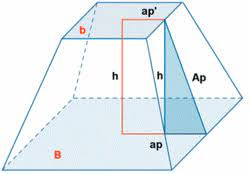

## Solución 1

clear
AB = 5*5;       % AB está en m^2
Ab = 2*2;       % Ab está en m^2
h = linspace(100, 3000, 10);    % h está en cm
h = h * 1e-2    % h está en m

h =     1.0000    4.2222    7.4444   10.6667   13.8889   17.1111   20.3333   23.5556   26.7778   30.0000


V = h./3.*(AB + Ab + (AB.*Ab).^(1/2))

V =    13.0000   54.8889   96.7778  138.6667  180.5556  222.4444  264.3333  306.2222  348.1111  390.0000


## Enunciado 2

Ahora se sabe que el volumen varía de 50 a 100 ${\mathrm{m}}^3$. Escoger un número razonable de volúmenes y **determinar la distancia vertical** que éstos tendrían considerando las mismas áreas del ejercicio anterior.

## Solución 2


$$V=\frac{h}{3}\left(A_B +A_b +\sqrt{A_B A_b }\right)$$


expr1 = (AB + Ab + (AB.*Ab).^(1/2))./3;
V = 50:5:100

V =     50    55    60    65    70    75    80    85    90    95   100


h = V ./ expr1

h =     3.8462    4.2308    4.6154    5.0000    5.3846    5.7692    6.1538    6.5385    6.9231    7.3077    7.6923



$$V=\frac{h}{3}\left(A_B +A_b +\sqrt{A_B A_b }\right)$$



$$\mathrm{expr1}=\frac{\left(A_B +A_b +\sqrt{A_B A_b }\right)}{3}$$



$$V=h\times \mathrm{expr1}$$
